## sls example usage

#### Sea Level Science

### Example for BODC tide gauge data at Portsmouth

#### Loading data and calculating parameters

Get site information for Portsmouth.

[latlon, site_name, site_code, od_value] = sls.bodc.tide_gauge_info("portsmouth")

latlon =    50.8022   -1.1113


site_name = "Portsmouth"

site_code = "PTM"

od_value = -2.7300

Load the tide gauge data downloaded from the BODC for Portsmouth and convert to Ordnance Datum (you could also convert the data manually using the 'od_value' but it is recommended to do this within the loading function as this does not adjust -99 data that will be removed during flagged data removal).

data = sls.bodc.load(site_code, "example_data/Portsmouth", "od");
head(data)

            time            water level (od) (m)    wl flags    residual (m)    rs flags
    ____________________    ____________________    ________    ____________    ________

    01-Jan-1991 00:00:00            -99               "N"           -99           "N"   
    01-Jan-1991 01:00:00            -99               "N"           -99           "N"   
    01-Jan-1991 02:00:00            -99               "N"           -99           "N"   
    01-Jan-1991 03:00:00            -99               "N"           -99           "N"   
    01-Jan-1991 04:00:00            -99               "N"           -99           "N"   
    01-Jan-1991 05:00:00            -99               "N"           -99           "N"   
    01-Jan-1991 06:00:00            -99               "N"           -99           "N"   
    01-Jan-1991 07:00:00    

Remove specified flagged data from all variables in the table 'data'.

data = sls.bodc.flag_removal(data, flags_to_del=["M", "N", "O", "X"]);
head(data)

            time            water level (od) (m)    wl flags    residual (m)    rs flags
    ____________________    ____________________    ________    ____________    ________

    01-Jan-1991 00:00:00            NaN               "N"           NaN           "N"   
    01-Jan-1991 01:00:00            NaN               "N"           NaN           "N"   
    01-Jan-1991 02:00:00            NaN               "N"           NaN           "N"   
    01-Jan-1991 03:00:00            NaN               "N"           NaN           "N"   
    01-Jan-1991 04:00:00            NaN               "N"           NaN           "N"   
    01-Jan-1991 05:00:00            NaN               "N"           NaN           "N"   
    01-Jan-1991 06:00:00            NaN               "N"           NaN           "N"   
    01-Jan-1991 07:00:00    

Calculate the predicted tide on the same timesteps as the input data, using a year-by-year harmonic analysis. Then remove the tide from the water levels to get the non-tidal residual.

[data.("predicted tide"), ~] = sls.calc_tide(data.("time"), data.("water level (od) (m)"), latlon(1));

Tidal analysis year by year: 1991 1992 1993 1994 1995 1996 1997 1998 1999 2000 2001 2002 2003 2004 2005 2006 2007 2008 2009 2010 2011 2012 2013 2014 2015 2016 2017 2018 2019 2020 2021

data.("non-tidal residual") = data.("water level (od) (m)") - data.("predicted tide");
head(data(:, ["predicted tide", "non-tidal residual"]))

    predicted tide    non-tidal residual
    ______________    __________________

         1.8618              NaN        
         1.5855              NaN        
        0.74249              NaN        
       -0.60813              NaN        
        -1.5841              NaN        
        -1.5655              NaN        
        -1.0036              NaN        
       -0.57738              NaN        



Calculate tidal high/low waters.

[high_waters, low_waters] = sls.high_low_water(data.("time"), data.("predicted tide"));
head(high_waters)

            time            high water
    ____________________    __________

    01-Jan-1991 00:00:00      1.8618  
    01-Jan-1991 11:00:00      1.9956  
    02-Jan-1991 00:00:00      2.0036  
    02-Jan-1991 12:00:00      2.0514  
    03-Jan-1991 01:00:00       2.038  
    03-Jan-1991 13:00:00      2.0296  
    04-Jan-1991 02:00:00       2.018  
    04-Jan-1991 14:00:00      1.9341  



head(low_waters)

            time            low water
    ____________________    _________

    01-Jan-1991 04:00:00     -1.5841 
    01-Jan-1991 17:00:00     -1.9625 
    02-Jan-1991 05:00:00     -1.7434 
    02-Jan-1991 18:00:00     -1.9789 
    03-Jan-1991 06:00:00     -1.7934 
    03-Jan-1991 18:00:00     -1.9641 
    04-Jan-1991 07:00:00     -1.6924 
    04-Jan-1991 19:00:00     -1.9374 



Calculate tidal phase (time to nearest high water).

tidal_phase = sls.tidal_phase(data.("time"), high_waters.("time"));
head(tidal_phase)

     0
     1
     2
     3
     4
     5
    -5
    -4



Remove mean sea level trends.

data.("wl detrended") = sls.remove_msl(data.("time"), data.("water level (od) (m)"));

head(data.("wl detrended"))

   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN



Calculate skew surge. Skew surge requires a simple sinusodial tide to accurately track high/low waters. First calculate this using sls.calc_tide and a low number of constiutents. The time input for skew surge is repeated here as a tidal timeseries on a different temporal resolution can be given. See function documentation for all argument options.

[s_tide, ~] = sls.calc_tide(data.("time"), data.("water level (od) (m)"), latlon(1), ncnstits=4);

Tidal analysis year by year: 1991 1992 1993 1994 1995 1996 1997 1998 1999 2000 2001 2002 2003 2004 2005 2006 2007 2008 2009 2010 2011 2012 2013 2014 2015 2016 2017 2018 2019 2020 2021

skew_surge = sls.skew_surge(data.("time"), data.("water level (od) (m)"), data.("time"), data.("predicted tide"), s_tide);

Default 6 hour window is being used - may not be suitable for your site!


head(skew_surge)

    skew surge     time to tidal high water from actual high water    time of tidal high water    tidal high water    time of actual high water    actual high water    percentage of sea level nans in window    timestep of prior value -> actual high water (hours)    time to nearest non-nan before hw (hours)    time to nearest non-nan after hw (hours)
    ___________    _______________________________________________    ________________________    ________________    _________________________    _________________    ______________________________________    ____________________________________________________    _________________________________________    ______

Plot skew surge. Notice there are some suspect low values.

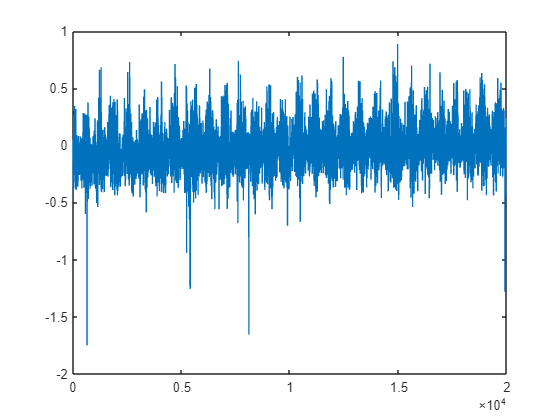

plot(skew_surge.("skew surge"))

Remove skew surges where there were > 50% of nans in the calculation window.

skew_surge(skew_surge.("percentage of sea level nans in window") > 50, :) = [];

Plot skew surge again to see the low values were caused by NaN values in the calculation windows.

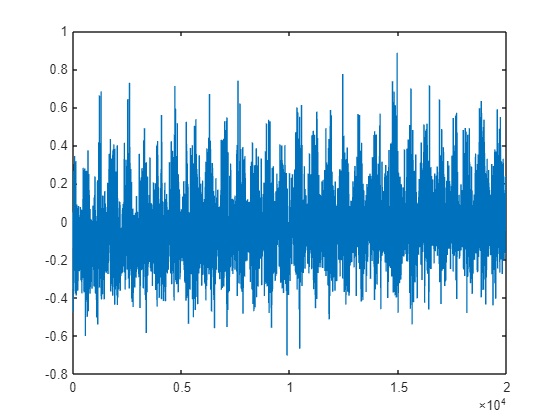

plot(skew_surge.("skew surge"))

Plot all the timeseries.

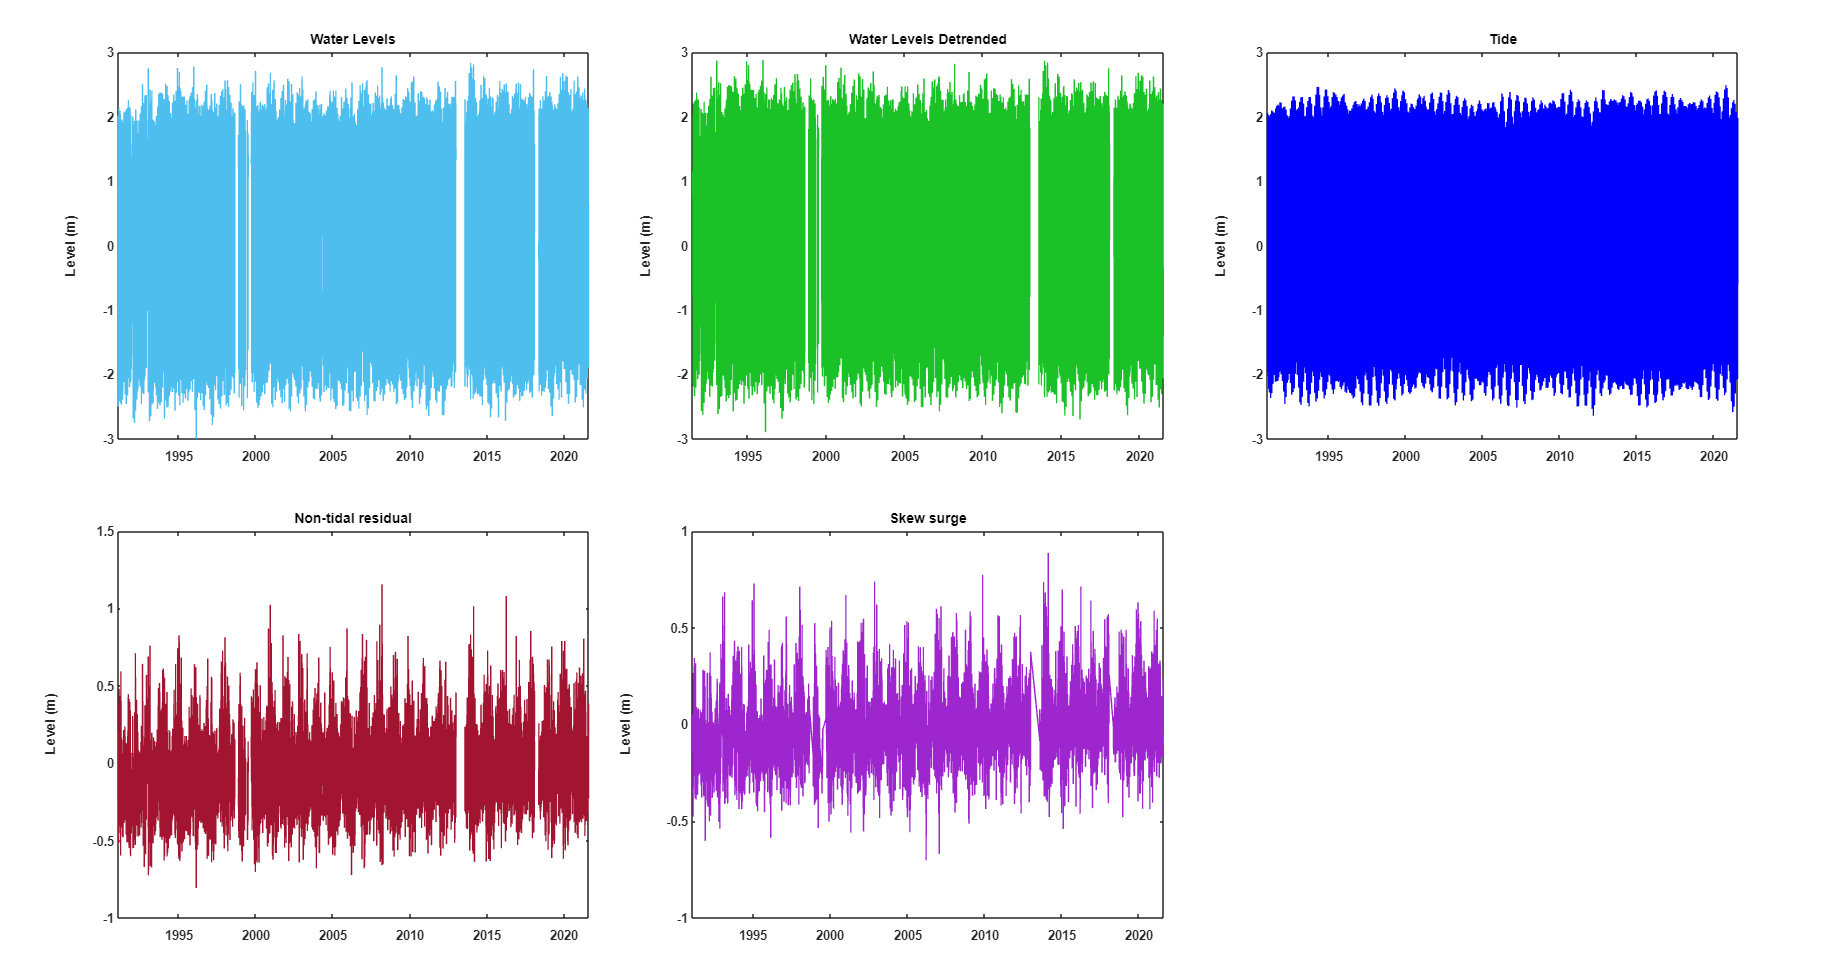

figure
sls.plt.timeseries(...
    data.("time"), data.("water level (od) (m)"), '#4DBEEE', ["Level (m)", "Water Levels"], ...
    data.("time"), data.("wl detrended"), [0.107 0.76 0.154], ["Level (m)", "Water Levels Detrended"], ...
    data.("time"), data.("predicted tide"), 'b', ["Level (m)", "Tide"], ...
    data.("time"), data.("non-tidal residual"), [0.6350 0.0780 0.1840], ["Level (m)", "Non-tidal residual"] , ...
    skew_surge.("time of tidal high water"), skew_surge.("skew surge"), [0.62 0.150 0.81], ["Level (m)", "Skew surge"]...
    )

Plot the time to predicted high water (tidal phase) from skew surge.

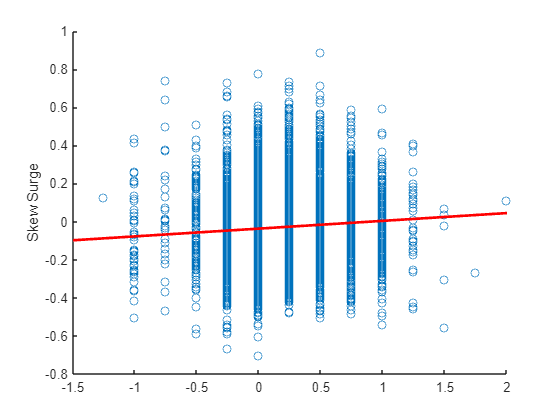

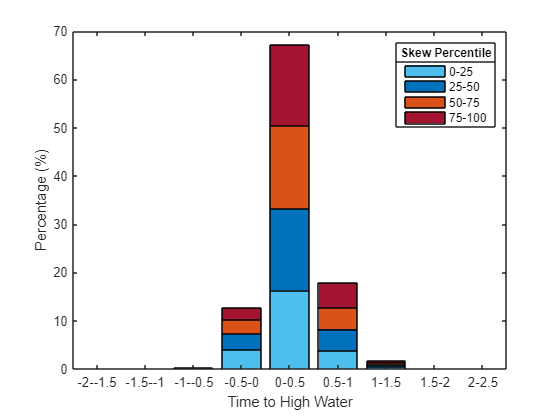

figure
scatter(hours(skew_surge.("time to tidal high water from actual high water")),skew_surge.("skew surge"))
lsl = lsline; lsl.Color = 'r'; lsl.LineWidth = 2;
ylabel('Skew Surge')

bins = hours(duration(-2, 0, 0)):hours(duration(0, 30, 0)):hours(duration(2, 30, 0)); % use bins of x axis (hours) from tile 1
groups = sls.groupbin(skew_surge.("skew surge"), [25 50 75], prcntile='y');
lg_labels = sls.plt.binlabels([0 25 50 75], rightedge="100");

sls.plt.twogroup_stacked_hist(hours(skew_surge.("time to tidal high water from actual high water")), bins, groups, ...
    percentage="y", colors=["#4DBEEE"; "#0072BD"; "#D95319"; "#A2142F"], addtofig="y", ...
    xlabel="Time to High Water", lgtitle="Skew Percentile", String=lg_labels)

#### Calculating return levels

First, get declustered exceedances (using *R-largest* method) for detrended water levels using the 99th percentile as a threshold and a storm window of 32 hours.

threshold = prctile(data.("wl detrended"), 99);
storm_window = 32;
[peaks_over_threshold, time_between_exc] = sls.rPOT(data.("time"), data.("wl detrended"), threshold, storm_window);
head(peaks_over_threshold)

           times            Rover 
    ____________________    ______

    23-Dec-1995 11:45:00    2.8794
    11-Jan-1993 13:15:00    2.8653
    06-Dec-2013 01:00:00    2.8647
    10-Jan-1993 12:30:00    2.8613
    07-Dec-1994 02:00:00    2.8596
    14-Feb-2014 23:00:00    2.8369
    10-Mar-2008 13:00:00    2.8209
    19-Jan-1995 13:00:00    2.7971



Plot the time between those declustered exceedances.

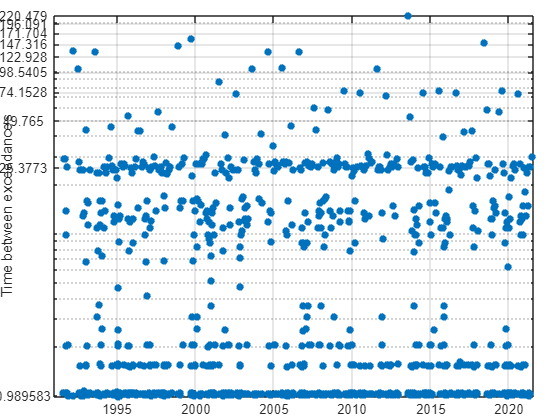

sls.plt.time_between_exceedances(time_between_exc, data.("time"), linspace(min(time_between_exc.("time between")), max(time_between_exc.("time between")), 10))

Alternatively, calculate the percentile threshold that gives *n *exceedances per year/time period.

n_per_year = 3;
[n_threshold, prctile_lvl, thresh_n_py] = sls.perc_thresh_n_py(data.("time"), data.("wl detrended"), n_per_year, storm_window, timeperiod="NA storm season")

n_threshold = 2.4340

prctile_lvl = 99.9000

thresh_n_py = 6.1613

peaks_over_threshold = sls.rPOT(data.("time"), data.("wl detrended"), n_threshold, storm_window);
head(peaks_over_threshold)

           times            Rover 
    ____________________    ______

    23-Dec-1995 11:45:00    2.8794
    11-Jan-1993 13:15:00    2.8653
    06-Dec-2013 01:00:00    2.8647
    10-Jan-1993 12:30:00    2.8613
    07-Dec-1994 02:00:00    2.8596
    14-Feb-2014 23:00:00    2.8369
    10-Mar-2008 13:00:00    2.8209
    19-Jan-1995 13:00:00    2.7971



Calculate return levels. The second input can be block maxima (such as the annual maxima calculated below), or declustered exceedances over a threshold as done here.

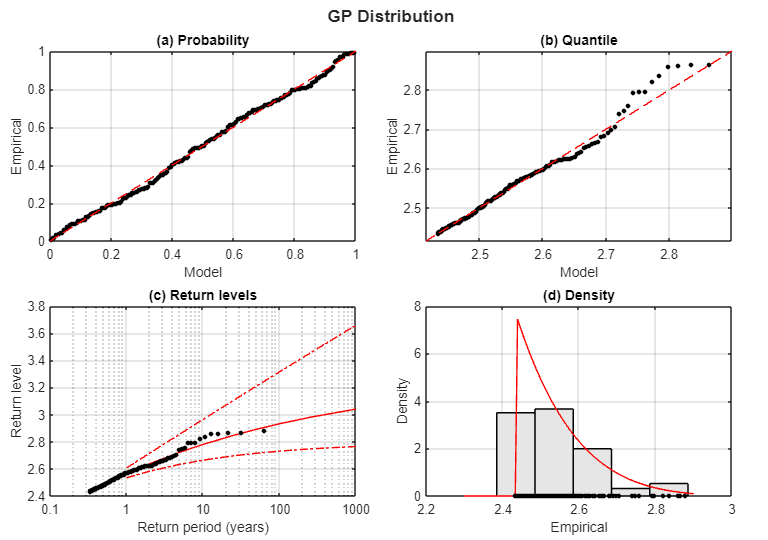

return_levels = 1.0e+03 *

    0.0010    0.0025    0.0026    0.0026
    0.0020    0.0026    0.0026    0.0027
    0.0050    0.0026    0.0027    0.0029
    0.0100    0.0027    0.0028    0.0030
    0.0250    0.0027    0.0028    0.0031
    0.0500    0.0027    0.0029    0.0032
    0.1000    0.0027    0.0029    0.0033
    0.2500    0.0027    0.0030    0.0035
    1.0000    0.0028    0.0030    0.0037


rl_stats = struct with fields:
    paramEsts: [-0.1486 0.1295]
     paramCIs: [2×2 double]
     paramSEs: [2×1 double]
         mean: 0.1128
     variance: 0.0098
      nloglik: -227.7356
         acov: [2×2 double]


[return_levels, rl_stats] = sls.return_levels("gp", peaks_over_threshold.("Rover"), threshold=n_threshold, avgpy=n_per_year, plot="y")

#### Descriptive statistics

Calculate the annual minima and maxima for detrended water levels and non-tidal residual.

mx_mn = sls.timeperiod_minmax("both", "yearly", data.("time"), data.("wl detrended"), data.("time"), data.("non-tidal residual"));
head(mx_mn)

    Time Period       Time of min 1         min 1        Time of max 1        max 1        Time of min 2         min 2         Time of max 2         max 2 
    ___________    ____________________    _______    ____________________    ______    ____________________    ________    ____________________    _______

       1991        11-Aug-1991 05:00:00    -2.3379    28-Sep-1991 14:00:00    2.3725    20-Nov-1991 10:00:00    -0.60092    04-Apr-1991 09:00:00    0.59177
       1992        20-Feb-1992 18:00:00    -2.6301    30-Aug-1992 00:00:00    2.6168    10-Oct-1992 03:00:00    -0.67067    12-Mar-1992 23:00:00    0.70983
       1993        08-Feb-1993 17:45:00     -2.612    11-Jan-1993 13:

Get counts for the peaks over threshold data over a given timeperiod. Using the 1 in 1- and 5-year return levels.

pot_counts = sls.POT_counts({peaks_over_threshold, data.("time")}, return_levels([1 3], 3), "NA storm season");
head(pot_counts)

       times       RL 1: 2.5653 count    RL 2: 2.7228 count
    ___________    __________________    __________________

    01-Jul-1991            0                     0         
    01-Jul-1992            1                     2         
    01-Jul-1993            2                     0         
    01-Jul-1994            3                     3         
    01-Jul-1995            2                     1         
    01-Jul-1996            1                     0         
    01-Jul-1997            2                     0         
    01-Jul-1998            1                     0         



Get the time between (non declustered) exceedance groups over the 1 in 5-year return level.

[cal_times_between, datenum_times_between, right_edges] = sls.time_between_exceedance_groups(data.("wl detrended"), return_levels(3, 3), data.("time"))

cal_times_between = 13×1 calendarDuration array
               23h 45m 0s
   1y 10mo 22d 22h 15m 0s
            2d 13h 45m 0s
        1mo 12d 9h 45m 0s
        11mo 3d 22h 0m 0s
         4y 1d 11h 45m 0s
      11mo 17d 23h 15m 0s
    7y 2mo 26d 12h 30m 0s
    5y 8mo 25d 11h 15m 0s
           27d 21h 15m 0s
                12h 0m 0s
       1mo 11d 10h 15m 0s
   3y 10mo 20d 13h 15m 0s


datenum_times_between = 1.0e+03 *

    0.0010
    0.6919
    0.0026
    0.0434
    0.3379
    1.4625
    0.3540
    2.6445
    2.0965
    0.0279


right_edges = 13×1 datetime array
   11-Jan-1993 12:45:00
   04-Dec-1994 11:45:00
   07-Dec-1994 01:30:00
   19-Jan-1995 12:45:00
   23-Dec-1995 11:15:00
   25-Dec-1999 00:00:00
   12-Dec-2000 23:45:00
   10-Mar-2008 12:30:00
   06-Dec-2013 00:30:00
   03-Jan-2014 00:00:00
   03-Jan-2014 12:15:00
   14-Feb-2014 22:45:00
   04-Jan-2018 12:45:00


Get information about the amount of time (in hours) (non declustered) exceedances stay above a threshold in a timeseries. Using the 1 in 5-year return level.

timeabv = sls.time_above_thresh(data.("time"), data.("wl detrended"), return_levels(3, 3))

timeabv = struct with fields:
      mean: 0.9464
    median: 0.8750
      mode: 0.5000
       max: 2.5000


Delete all bar the max of consecutive values over the 1 in 5-year return level threshold.

var_tcd = sls.thresh_cross_del(data.("wl detrended"), return_levels(3, 3));
head(var_tcd)

   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN

